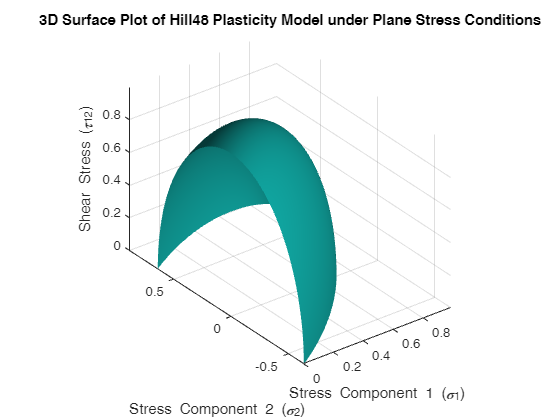

% Constants for the Hill 1948 plasticity model
Sig00 = 1; % Yield stress in uniaxial tension along the rolling direction
Sig90 = .9; % Yield stress in uniaxial tension along the transverse direction
Sigb = 1.2; % Yield stress in uniaxial tension along the normal direction

% Calculate F1, G1, and H1 coefficients
F1 = (Sig00/Sig90)^2 - 1 + (Sig00/Sigb)^2;
G1 = 1 - (Sig00/Sig90)^2 + (Sig00/Sigb)^2;
H1 = 1 + (Sig00/Sig90)^2 - (Sig00/Sigb)^2;

% Range of stress components
sigma1_range = linspace(0, 2, 100);
sigma2_range = linspace(-2, 2, 100);
tau12_range = linspace(0, 2, 100);

% Create a meshgrid for stress components
[sigma1, sigma2, tau12] = meshgrid(sigma1_range, sigma2_range, tau12_range);

% Calculate the Hill48 yield function value for plane stress conditions (sigma3 = 0)
hill48 = (G1 + H1) * (sigma1.^2) + (F1 + H1) * (sigma2.^2) - 2 * H1 * sigma1 .* sigma2 + (tau12.^2);

% Find the surface where Hill48 yield function equals 1
isosurface_threshold = 1;

% Create a 3D surface plot
figure;
isosurface(sigma1, sigma2, tau12, hill48, isosurface_threshold);
xlabel('Stress Component 1 (\sigma_1)');
ylabel('Stress Component 2 (\sigma_2)');
zlabel('Shear Stress (\tau_{12})');
title('3D Surface Plot of Hill48 Plasticity Model under Plane Stress Conditions');
axis equal;
grid on;
view(3);